# How to read in and analyze multi device, single session snirf data in Matlab

Here, we  investigate how to read in data saved in [**snirf format**](https://github.com/fNIRS/snirf/) and process those data with [**Homer3**](https://github.com/BUNPC/Homer3). The dataset we present here was recorded using two [**Brite MKII (Artinis Medical Systems B.V., Elst, The Netherlands)**](https://www.artinis.com/brite) running in dual mode. The optodes of both Brites were placed over the left and right prefrontal and parietal cortices

The subject was sitting in a chair in front of a computer screen. The experiment started with a resting period of approximately 30 seconds followed by an [**n-back task**](https://en.wikipedia.org/wiki/N-back) of 30 seconds. These two periods were repeated 10 times. 

## Defining helper variables

We define the variable *fname *pointing* to *the location of the data file used in this script. In addition, we define the variables *transmitter_id* and *receiver_id* containing the transmitter and receiver IDs of the channels positioned over the frontal cortex for each device. Another variable (*dpf*) is defined containing the differential pathlength factor (DPF) used in modified Beer-Lambert law. 

datadir = 'two_devices_n_back';
fname = fullfile(datadir, 'D_2023.snirf');

transmitter_id = [1,3,1,4,5,3,3,4,5]; % Prefrontal and frontal channels of the first Brite
receiver_id = [1,1,2,2,3,3,4,4,4]; % Prefrontal and frontal channels of the first Brite
numberOftransmittersPerDevice = 10;
numberOfreceiversPerDevice = 8;
transmitter_id = [transmitter_id, transmitter_id+numberOftransmittersPerDevice];
receiver_id = [receiver_id, receiver_id+numberOfreceiversPerDevice];
dpf = 6.06;


## Homer 3

From here on, we start using [**Homer3**](https://github.com/BUNPC/Homer3) functions. You need to make sure to add the respective functions that we need to your Matlab path (e.g. using the [**addpath**](https://www.mathworks.com/help/matlab/ref/addpath.html) command). 

We use the following paths / functions:

Located in Homer3\DataTree\AcquiredData\Snirf\:

- [*SnirfClass*](https://github.com/BUNPC/Homer3/blob/master/DataTree/AcquiredData/Snirf/SnirfClass.m) to read in the snirf file

Located in Homer3\FuncRegistry\UserFunctions:

- [*hmrR_Intensity2OD*](https://github.com/BUNPC/Homer3/blob/master/FuncRegistry/UserFunctions/hmrR_Intensity2OD.m) to convert raw data into ODs

- [*hmrR_BandpassFilt*](https://github.com/BUNPC/Homer3/blob/master/FuncRegistry/UserFunctions/hmrR_BandpassFilt.m) to bandpass filter the data

- [*hmrR_OD2Conc*](https://github.com/BUNPC/Homer3/blob/master/FuncRegistry/UserFunctions/hmrR_OD2Conc.m) to convert ODs to (relative change in) concentrations 

- [*hmrR_BlockAvg*](https://github.com/BUNPC/Homer3/blob/master/FuncRegistry/UserFunctions/hmrR_BlockAvg.m) to compute the trial/block average 

Eventually, we loop through our three datasets to compute the average across sessions and plot those.

## Loading the data file

We load the data file of the n-back experiment using the SnirfClass. 

acquired = SnirfClass(fname);

## Preprocess the data

First, we process the data by converting the intensity signals to optical densities (ODs). The ODs are then fitered by using a band-pass filter [0.01-0.1] Hz such that the frequency of the hemodynamic response remains and frequencies of other signal components are filtered out. Finally, we convert the filtered ODs to concentration changes in oxygenated hemoglobin (HbO) and deoxygenated hemoglobin (HbR) signals by using the modifed Beer-Lambert law. 

dod = hmrR_Intensity2OD(acquired.data); 
dod = hmrR_BandpassFilt(dod, 0, 0.1);
dc  = hmrR_OD2Conc(dod, acquired.probe, [dpf,dpf]);


## Block averaging

In this step, we compute the average of n-back trials for all channels. First, we define the time range tRangeinSeconds, and then compute the block average of the concentration data starting 5 seconds before the desired events (pre-stimulus) and ending 30 seconds after them (post-stimulus) is computed. 

trangeInSeconds = [-5, 30]; 
[dcAvgSubjs, ~, ~, ~] = hmrR_BlockAvg(dc, acquired.stim(2), trangeInSeconds);

## Extract channels of interest

Next, we need to extract the channels of interest by checking the transmitter and receiver indices (note that they are called source and detector in Homer). Once done, we transform the units to be in micromolar and then compute the mean activation in our channels of interest.

oxy_scaled_all = [];
dxy_scaled_all = [];
for idx_main = 1:numel(receiver_id)
    transmitter_id0 = transmitter_id(idx_main);
    receiver_id0 = receiver_id(idx_main);
    for idx=1:numel(dcAvgSubjs.measurementList)
        s_id0 = dcAvgSubjs.measurementList(1, idx).sourceIndex;  
        d_id0 = dcAvgSubjs.measurementList(1, idx).detectorIndex; 
        if(s_id0 == transmitter_id0 && d_id0 == receiver_id0)
            oxy_id = idx;
            break;
        end
    end
    dxy_id = oxy_id+1;
    oxy = dcAvgSubjs.dataTimeSeries(:,oxy_id);
    dxy = dcAvgSubjs.dataTimeSeries(:,dxy_id);
	molToMuMolConversionFactor = 1e6;
    oxy_scaled = oxy * molToMuMolConversionFactor;
    dxy_scaled = dxy * molToMuMolConversionFactor;
    oxy_scaled_all = [oxy_scaled_all , oxy_scaled];
    dxy_scaled_all = [dxy_scaled_all , dxy_scaled];
end
oxy_scaled_avg = mean(oxy_scaled_all, 2);
dxy_scaled_avg = mean(dxy_scaled_all, 2);
time = dcAvgSubjs.time;

## Plotting

Here, we plot the resulting O2Hb (HbO) and HHB (HbR) signals in micromol, shown in red and blue, respectively, using standard Matlab functions.  

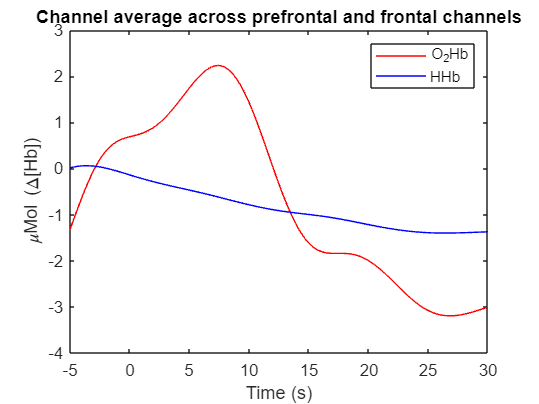

figure;
plot(time,oxy_scaled_avg,'r');
hold on;
plot(time,dxy_scaled_avg, 'b')
xlabel('Time (s)')
ylabel('\muMol (\Delta[Hb])')
legend('O_{2}Hb', 'HHb')
title('Channel average across prefrontal and frontal channels');
xlim([-5, 30])